clc;clear;
nMems = 3;
alpha = 95;
N = 400;

dirs = dir(fullfile("Data", "N"+num2str(N), num2str(nMems) + "memories"));
file = fullfile(dirs(3).folder, dirs(3).name, "recallsResponses", "alpha_" + num2str(alpha)+ ".mat");
load(file)
whos

  Name                      Size               Bytes  Class     Attributes

  N                         1x1                    8  double              
  X_responseActivity      400x400            1280000  double              
  Y_memoryClass           400x1                 3200  double              
  alpha                     1x1                    8  double              
  dirs                     14x1                14679  struct              
  file                      1x1                  486  string              
  nMems                     1x1                    8  double              



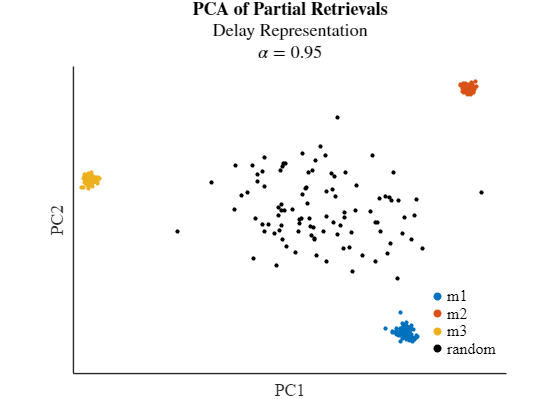



X_responseActivity(isnan(X_responseActivity)) = 0;
[coeff, score, latent, tsquared, explained] = pca(X_responseActivity);

% Get unique memory classes
memoryLabels = unique(Y_memoryClass);

% Generate colormap
cmap = lines(nMems);

% Plot with loop
figure; hold on;
for i = 1:nMems
    idx = Y_memoryClass == i;
    % scatter3(score(idx, 1), score(idx, 2), score(idx, 3), 10, cmap(i, :), 'filled', ...
    %     'DisplayName', "m" + num2str(memoryLabels(i)));
    scatter(score(idx, 1), score(idx, 2), 10, cmap(i, :), 'filled', ...
    'DisplayName', "m" + num2str(memoryLabels(i)));
end

idx = Y_memoryClass == nMems+1;
% scatter3(score(idx, 1), score(idx, 2), score(idx, 3), 10, 'k', 'filled', ...
%     'DisplayName', "random");
scatter(score(idx, 1), score(idx, 2), 10, 'k', 'filled', ...
    'DisplayName', "random");

xlabel('PC1'); ylabel('PC2'); zlabel('PC3');
title({'\textbf{PCA of Partial Retrievals}', 'Delay Representation', "$\alpha=$" + num2str(0.01*alpha)}, 'Interpreter', 'latex','FontName', 'Times New Roman', 'FontSize', 12);
legend('Location', 'best', 'FontName', 'Times New Roman', 'FontSize', 12, 'Box','off');

% view(3); zticks([]);
xticks([]); yticks([]); 
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12)
print(sprintf("PCA_AlternatingLearningAlpha%d.png", alpha), '-dpng', '-r300')
exportgraphics(gcf, sprintf("PCA_AlternatingLearningAlpha%d.pdf", alpha), 'ContentType', 'vector');